# RUN 1st

# LOAD DATA

tic
RegionID = 'FRA';
% timespan indicates the set of data we need to load. E.g., 2016/12 to 2022/12 
timespan = datetime(2015,12,1):calmonths(1):datetime(2022,12,1);
% PlantName are Wivenhoe, Shoalhaven, Tumut3. Case insensitive, e.g. ShOalHaVen is fine.
CGdata = funcCoalGasdata(timespan, RegionID)

CGdata = 70128×4 table
       SETTLEMENTDATE       Coal    Gas     RRP
    ____________________    ____    ____    ___

    01-Jan-2015 00:00:00    2025    2823     0 
    01-Jan-2015 01:00:00    1577    2515     0 
    01-Jan-2015 02:00:00    1416    2452     0 
    01-Jan-2015 03:00:00    1132    2345     0 
    01-Jan-2015 04:00:00     770    2344     0 
    01-Jan-2015 05:00:00     861    2340     0 
    01-Jan-2015 06:00:00    1067    2318     0 
    01-Jan-2015 07:00:00    1083    2357     0 
    01-Jan-2015 08:00:00     965    2385     0 
    01-Jan-2015 09:00:00     984    2382     0 
    01-Jan-2015 10:00:00    1091    2364     0 
    01-Jan-2015 11:00:00    1052    2355     0 
    01-Jan-2015 12:00:00    1052    2352     0 
    01-Jan-2015 13:00:00    1008    2343     0 
    01-Jan-2015 14:00:00     998    2330     0 
    01-Jan-2015 15:00:00

PHSdata = funcPHSdata(timespan, RegionID,'cheylas')

PHSdata = 70128×4 table
       SETTLEMENTDATE       PHSgen    PHSpump    RRP
    ____________________    ______    _______    ___

    01-Jan-2015 00:00:00      0          0        0 
    01-Jan-2015 01:00:00      0          0        0 
    01-Jan-2015 02:00:00      0          0        0 
    01-Jan-2015 03:00:00      0          0        0 
    01-Jan-2015 04:00:00      0          0        0 
    01-Jan-2015 05:00:00      0          0        0 
    01-Jan-2015 06:00:00      0          0        0 
    01-Jan-2015 07:00:00      0          0        0 
    01-Jan-2015 08:00:00      0          0        0 
    01-Jan-2015 09:00:00      0          0        0 
    01-Jan-2015 10:00:00      0          0        0 
    01-Jan-2015 11:00:00      0          0        0 
    01-Jan-2015 12:00:00      0          0        0 
    01-Jan-2015 13:00:00      0          0  

VREdata = funcVREdata(timespan, RegionID)

VREdata = 70128×4 table
       SETTLEMENTDATE       Solar    Wind    RRP
    ____________________    _____    ____    ___

    01-Jan-2015 00:00:00       0     1314     0 
    01-Jan-2015 01:00:00       0     1383     0 
    01-Jan-2015 02:00:00       0     1464     0 
    01-Jan-2015 03:00:00       0     1543     0 
    01-Jan-2015 04:00:00       0     1579     0 
    01-Jan-2015 05:00:00       0     1482     0 
    01-Jan-2015 06:00:00       0     1387     0 
    01-Jan-2015 07:00:00       0     1583     0 
    01-Jan-2015 08:00:00      59     1814     0 
    01-Jan-2015 09:00:00     385     1936     0 
    01-Jan-2015 10:00:00    1053     1927     0 
    01-Jan-2015 11:00:00    1635     1846     0 
    01-Jan-2015 12:00:00    1883     1768     0 
    01-Jan-2015 13:00:00    1857     1715     0 
    01-Jan-2015 14:00:00    1516     1693     0 
    01

toc

Elapsed time is 0.334380 seconds.


Choose the period that we will do the analysis. Choose the window length for the calculation, for example, opts = 12 means 1-hour length

% hourly MWh
tic
% start date to end date indicates the time frame that we will do the
% analysis. Ofcourse, that time frame must be within the timespan.
start_date = 20180101; end_date = 20221231; opts = 2;
calcPHS = funcMWhAndAUD(PHSdata,start_date,end_date,opts);
calcVRE = funcMWhAndAUD(VREdata,start_date,end_date,opts);
calcCG = funcMWhAndAUD(CGdata,start_date,end_date,opts);
totalGL = funcTotalGenLoad(RegionID,timespan,start_date,end_date,opts)

totalGL = 21912×5 table
       SETTLEMENTDATE         genMWh      loadMWh    genAUD    loadAUD
    ____________________    __________    _______    ______    _______

    01-Jan-2018 00:00:00    1.1613e+05       0         0          0   
    01-Jan-2018 02:00:00    1.0998e+05       0         0          0   
    01-Jan-2018 04:00:00    1.0834e+05       0         0          0   
    01-Jan-2018 06:00:00    1.1105e+05       0         0          0   
    01-Jan-2018 08:00:00    1.1408e+05       0         0          0   
    01-Jan-2018 10:00:00    1.1718e+05       0         0          0   
    01-Jan-2018 12:00:00    1.1848e+05       0         0          0   
    01-Jan-2018 14:00:00    1.1746e+05       0         0          0   
    01-Jan-2018 16:00:00    1.2434e+05       0         0          0   
    01-Jan-2018 18:00:00

toc

Elapsed time is 0.256225 seconds.


% Daily MWh
tic
calcPHSdaily = funcMWhAndAUD(PHSdata,start_date,end_date,288);

Error using table (line 297)
Size must be a two-element vector of nonnegative integer values specifying the number of rows and the number of variables.

Error in funcMWhAndAUD (line 24)
calcData = table('Size',[records/opts 5],'VariableTypes',{'datetim

calcVREdaily = funcMWhAndAUD(VREdata,start_date,end_date,288);
calcCGdaily = funcMWhAndAUD(CGdata,start_date,end_date,288);
totalGLdaily = funcTotalGenLoad(RegionID,timespan,start_date,end_date,288);
toc

% Price volatility metrics
tic
[avrRRP, volat1, volat2] = funcAvrRRP(PHSdata(:,{'SETTLEMENTDATE','RRP'}),start_date,end_date,opts);
toc

Some other variables that may show us the relationships

tic
solarPcent=calcVRE.SolarMWh./totalGL.genMWh; solarPcentDaily=calcVREdaily.SolarMWh./totalGLdaily.genMWh;
windPcent=calcVRE.WindMWh./totalGL.genMWh; windPcentDaily=calcVREdaily.WindMWh./totalGLdaily.genMWh;
gasPcent=calcCG.GasMWh./totalGL.genMWh; gasPcentDaily=calcCGdaily.GasMWh./totalGLdaily.genMWh;
coalPcent=calcCG.CoalMWh./totalGL.genMWh; coalPcentDaily=calcCGdaily.CoalMWh./totalGLdaily.genMWh;
phsgenPcent=calcPHS.PHSgenMWh./totalGL.genMWh; phsgenPcentDaily=calcPHSdaily.PHSgenMWh./totalGLdaily.genMWh;
phspumpPcent=calcPHS.PHSpumpMWh./totalGL.genMWh; phspumpPcentDaily=calcPHSdaily.PHSpumpMWh./totalGLdaily.genMWh;
toc

# START THE ANALYSIS

Settings

tic
% smoothing window (moving average method)
sw=3; mt='';

## 1. VRE and Coal

% clf; hold on
v1 = solarPcentDaily+windPcentDaily; 
v2 = coalPcentDaily;
% h = height(v1); d = round(h/5);
% t1 = 1; t2 = d;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d; t2 = d*2;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*2; t2 = d*3;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*3; t2 = d*4;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*4; t2 = h;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% title('More VRE, Less Coal')

clf; 
plot(calcVREdaily.SETTLEMENTDATE,v1*100)
hold on
plot(v2*100)
title('Daily energy ratio from VRE (blue) and Coal (red)'); ylabel("%")
disp('1|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

v1 = smooth(volat2.DayMin,sw);
v2 = smooth(volat2.DayMax,sw);

clf; hold on
plot(volat2.SETTLEMENTDATE,v1)
plot(volat2.SETTLEMENTDATE,v2)
ylabel("Price ($/MWh)")
% title("Price spread")
legend("Daily low price","Daily high price")

legend('Position',[0.25978,0.80279,0.27126,0.092992])

## 2. Peaking generators: Gas and PHS - Outlook

v1 = gasPcentDaily;
v2 = phsgenPcentDaily;
clf; plot(calcVREdaily.SETTLEMENTDATE,v1*100); title('Daily energy ratio from GAS'); ylabel("%")
clf; plot(calcVREdaily.SETTLEMENTDATE,v2*100); title('Daily energy ratio from PHS generation'); ylabel("%")
disp('2|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

Need more firming capacity. PHS has been used more frequently. *ExtractPHSOperationOutlook* gives: 

### Increase of usage, Revenue - Cost

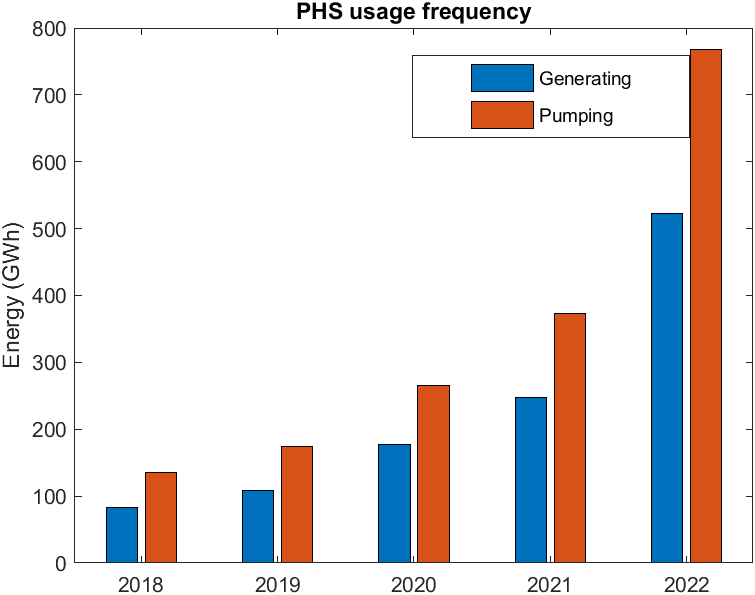 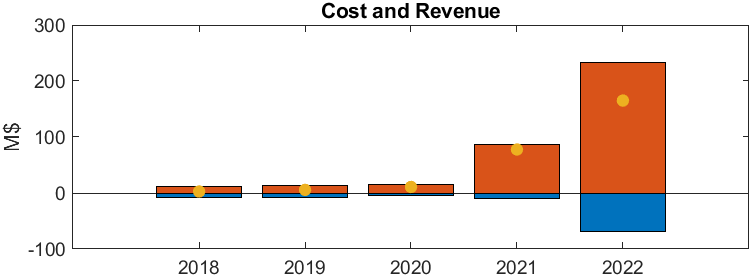

## 3. Natural Gas price raises DayMax

Gas% and average price, hourly. Correlation changes by each time interval, might be dependent on LNG price

v1 = 100*gasPcent; 
v2 = avrRRP.AvrRRP;

clf; hold on
h = height(v1); d = round(h/5);
t1 = 1; t2 = d;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d; t2 = d*2;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*2; t2 = d*3;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*3; t2 = d*4;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*4; t2 = h;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))

% clf;
% corr(v1,v2,"type","Spearman")
% scatter(v1,v2)
title("Gas% Vs. Average Price in Hourly")

xlim([-0.0 35.2])
ylim([-460 2000])
disp('3.1|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

Effect of GAS% on VOLATILITY (DayMax). Again, correlation changes by each time interval.

v1 = smooth(gasPcentDaily,sw);
v2 = smooth(volat2.DayMax,sw);

clf; 
yyaxis("left"); plot(volat2.SETTLEMENTDATE,100*v1); ylabel("Daily energy from Gas (%)")
yyaxis("right"); plot(v2); ylabel("Daily high price ($/MWh)")
title('Gas% vs. Volatility (DayMax) - Daily')

clf; hold on
h = height(v1); d = round(h/5);
t1 = 1; t2 = d;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d; t2 = d*2;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*2; t2 = d*3;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*3; t2 = d*4;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*4; t2 = h;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
title('Gas% vs. Volatility (DayMax) - Daily')
disp('3.2|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

Effect of LNG PRICE on VOLATILITY: raise daily high price

NGasPrice = funcNGasPrice("NGasPrice.csv", [367, Inf]);
% 2,Inf 2017->2022
% 367,Inf 2018->2022

v1 = NGasPrice.NGPrice;
v2 = smooth(volat2.DayMax,sw);
clf; 
yyaxis("left"); plot(NGasPrice.NGDate,v1); ylim([2 60]); ylabel("Liquefied Natural Gas price ($/GJ)")
yyaxis("right"); plot(v2); ylim([-20 2000]); ylabel("Daily high electricity price ($/MWh)")
title('Natural Gas price and Volatility (DayMax) - Daily')

clf;
scatter(v1,v2); title('Natural Gas price and Volatility (DayMax) - Daily')
txt = sprintf('corr = %.2f',corr(v1,v2,type="Spearman"));
text(5,1400,txt);

disp('3.3|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

## 4. VRE lowers DayMin

Moderate correlation

% v1 = 100*(windPcentDaily+solarPcentDaily);
v1 = 100*max(reshape(solarPcent,288/opts,[]))'; %solar daily swing
v2 = smooth(volat2.DayMin,sw);

% clf; hold on
% h = height(v1); d = round(h/5);
% t1 = 1; t2 = d;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d; t2 = d*2;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*2; t2 = d*3;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*3; t2 = d*4;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*4; t2 = h;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))

clf
scatter(v1,v2)
txt = sprintf('corr = %.2f',corr(v1,v2,type="Spearman"));
text(5,300,txt);

title('VRE% vs. Volatility (DayMin)')

xlim([-0.5 39.5])
ylim([-350 350])

% % distance from DayMin to Average
% dayAvr = totalGLdaily.genAUD./totalGLdaily.genMWh;
% dtance = volat2.DayMin-dayAvr;
% v2 = dtance;
% 
% clf
% corr(v1,v2,"type","Spearman")
% scatter(v1,v2)

disp('4|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

## 5. PHS - price taker

### Gen. price, Pump price

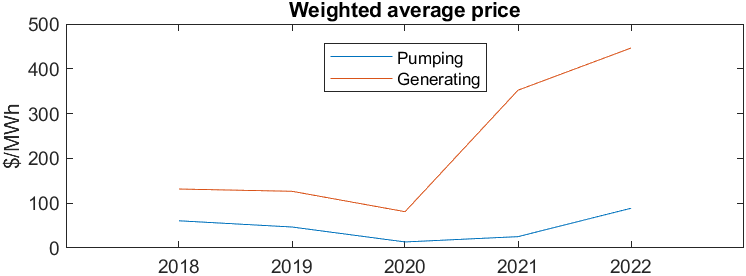

## Explanation

Peaking at sunrise/6am and sunset/6pm

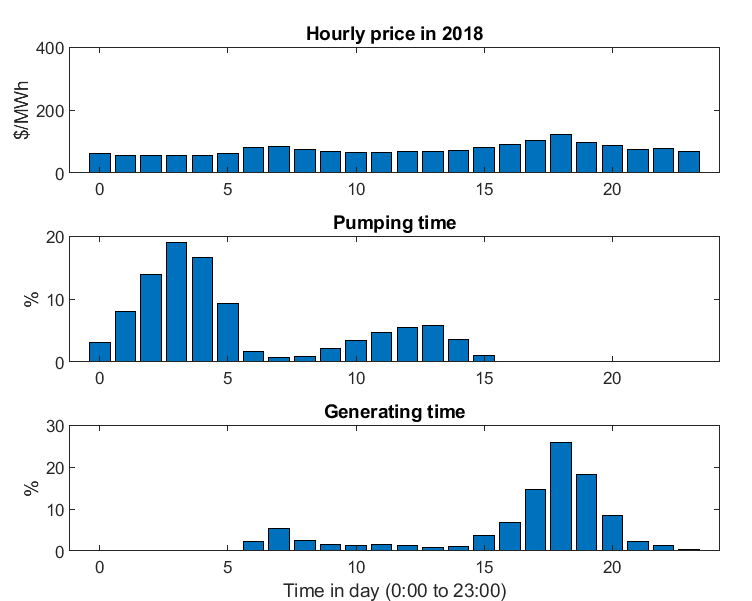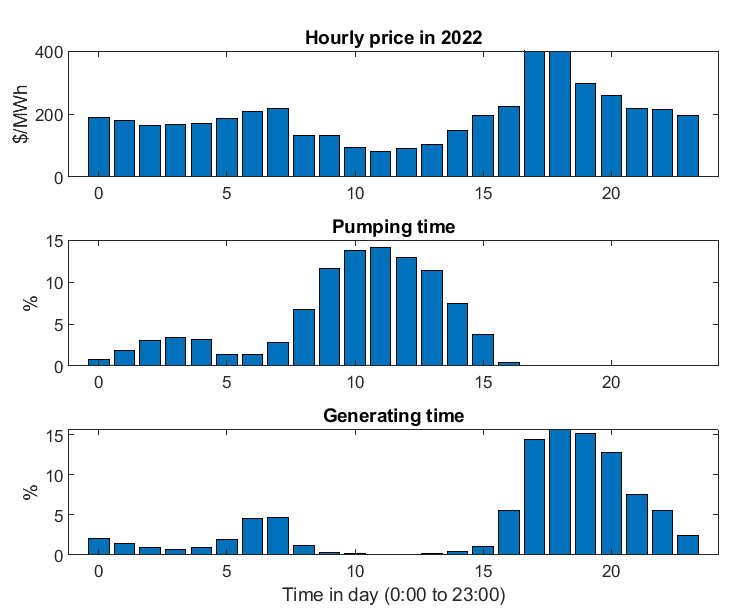

v1 = smooth(calcPHSdaily.PHSgenAUD-calcPHSdaily.PHSpumpAUD,sw);
v2 = smooth(volat2.Spread,sw);

clf; hold on
h = height(v1); d = round(h/5);
t1 = 1; t2 = d;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d; t2 = d*2;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*2; t2 = d*3;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*3; t2 = d*4;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))
t1 = d*4; t2 = h;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
scatter(v1(t1:t2),v2(t1:t2))

% clf; hold on
% yyaxis("left");plot(v1);
% yyaxis("right");plot(v2)

disp('5|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||')

% https://au.mathworks.com/help/curvefit/smoothing-data.html

% Pearson correlation coefficient measures the linear relationship (linear assumption)
% Spearman correlation coefficient measures the monotonic relationship (monotonic assumption), 
% which means that as one variable increases, the other variable either increases or decreases in a consistent manner

toc